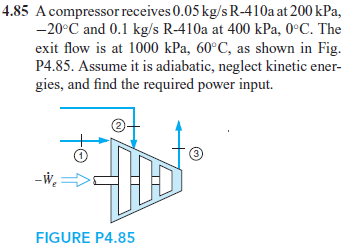

# symbolic units class

u = symunit;

# state 1 (superheated R-410a)

% ----------------
% given
mdot1 = 0.05*u.kg/u.s;
p1 = 200*u.kPa;
T1 = -20*u.Celsius;
% ----------------
% specific enthalpy
h1 = 278.72*u.kJ/u.kg;
% ----------------

# state 2 (superheated R-410a)

% ----------------
% given
mdot2 = 0.1*u.kg/u.s;
p2 = 400*u.kPa;
T2 = 0;
% ----------------
% specific enthalpy
h2 = 290.42*u.kJ/u.kg;
% ----------------

# state 3 (superheated R-410a)


% ----------------
% given
p3 = 1000*u.kPa;
T3 = 60*u.Celsius;
% ----------------
% specific enthalpy
h3 = 335.75*u.kJ/u.kg;
% ----------------

# conservation of mass

mdot3 = mdot1+mdot2;
mdot3_vpa = vpa(mdot3) %#ok

$$mdot3\_vpa = 0.15\,\frac{\mathrm{kg}}{s}$$

clear mdot3_vpa;

# conservation of energy

Wdot = sym('Wdot');
Wdot = rewrite(solve(mdot1*h1+mdot2*h2 == mdot3*h3+Wdot), u.kW);
Wdot_vpa = vpa(Wdot) %#ok

$$Wdot\_vpa = -7.3845\,\mathrm{kW}$$

clear Wdot_vpa;